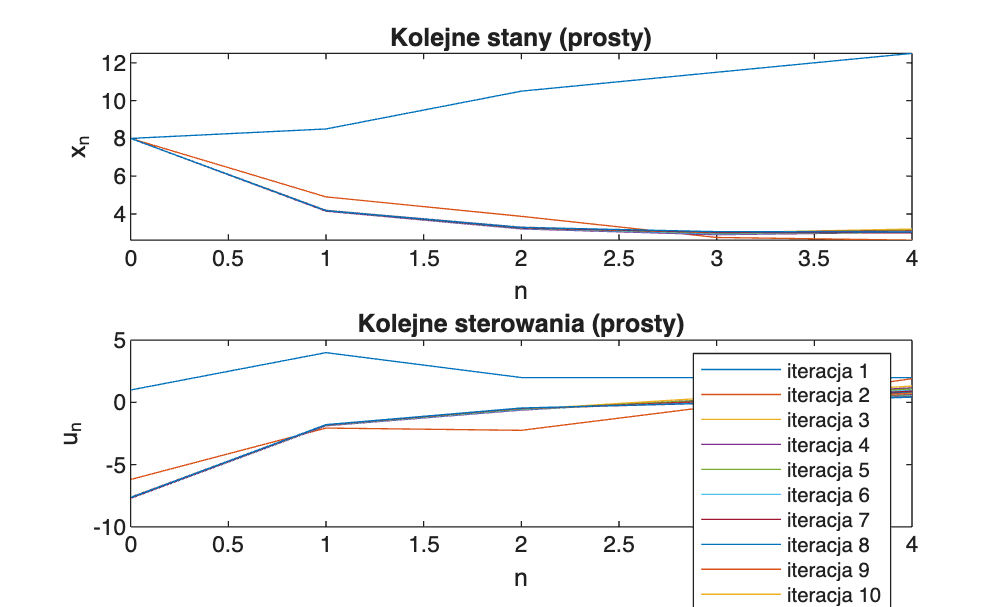

clear all;
close all;
clc;

K = 15;
t = 0.001;
e = 0.2;
x(1) = 8;
u = [1 4 2 2 2];
N = length(u);
c = 0;

r_stanu = @(x, u) x + 0.5*u;

L = @(x, u) (10*(x-3).^2 + u.^2);

J_fun = @(x, u) sum(L(x, u));

p(N+1) = 0;

syms xs us ps
Hn(xs, us, ps) = L(xs, us) + ps * r_stanu(xs, us);

pn_fun = matlabFunction(diff(Hn, xs));
bn_fun = matlabFunction(diff(Hn, us));

legenda = {};
k = 0;

while 1
    k = k + 1;

    for i = 2:N
        x(i) = r_stanu(x(i-1), u(i-1));
    end

    legenda{end+1} = ['iteracja ', num2str(k)];

    subplot(2,1,1);
    plot(0:N-1, x); hold on; title('Kolejne stany (prosty)'); xlabel('n'); ylabel('x_n');
    subplot(2,1,2);
    plot(0:N-1, u); hold on; title('Kolejne sterowania (prosty)'); xlabel('n'); ylabel('u_n');
    legend(legenda);

    J_plot_p(k) = J_fun(x, u);

    for i = N:-1:1
        p(i) = pn_fun(x(i), u(i), p(i+1));
        b(i) = bn_fun(x(i), u(i), p(i+1));
    end

    t = fminsearch(@(t) wyznacz_t(r_stanu, J_fun, x, u, N, b, t), t);

    u = u - t * b;

    if norm(b) < e || k >= K
        break
    end

end


J_plot_p

J_plot_p = 1.0e+03 *

    2.7690    0.3473    0.3289    0.3284    0.3280    0.3277    0.3275    0.3273    0.3272    0.3271    0.3270    0.3269    0.3268    0.3268    0.3267


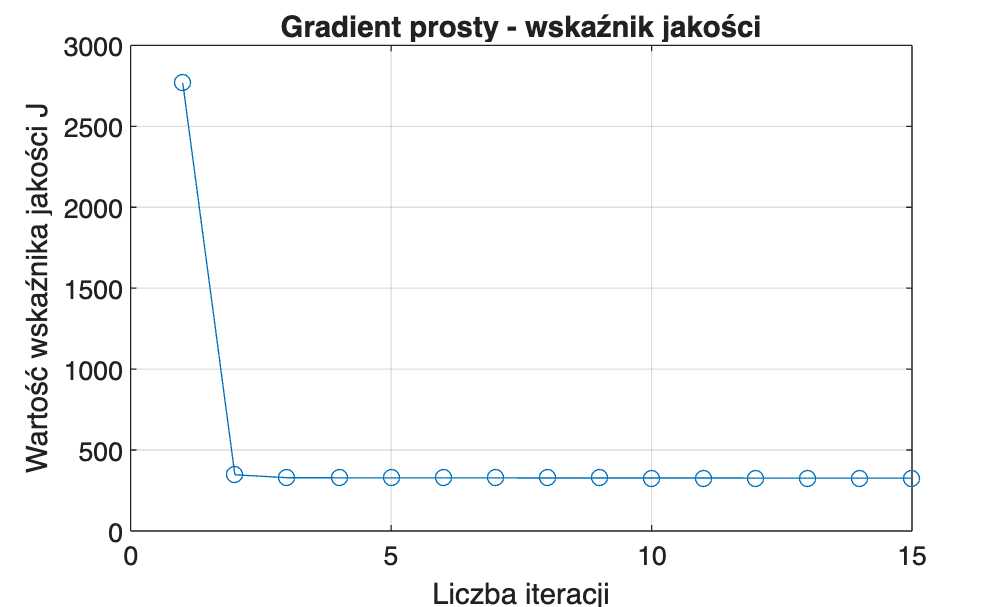


figure;
plot(1:k, J_plot_p, '-o');
title('Gradient prosty - wskaźnik jakości');
xlabel('Liczba iteracji');
ylabel('Wartość wskaźnika jakości J');
grid on;


% Funkcja do minimalizacji po t
function J_val = wyznacz_t(r_stanu, J_fun, x, u, N, b, t)
x_new = x;
for i = 2:N
    x_new(i) = r_stanu(x_new(i-1), u(i-1) - t*b(i-1));
end
u_new = u - t*b;
J_val = J_fun(x_new, u_new);
end

%------------------------------
u = [1 4 2 2 2];

Function definitions in a script must appear at the end of the file.
Move all statements after the "wyznacz_t" function definition to before the first local function definition.

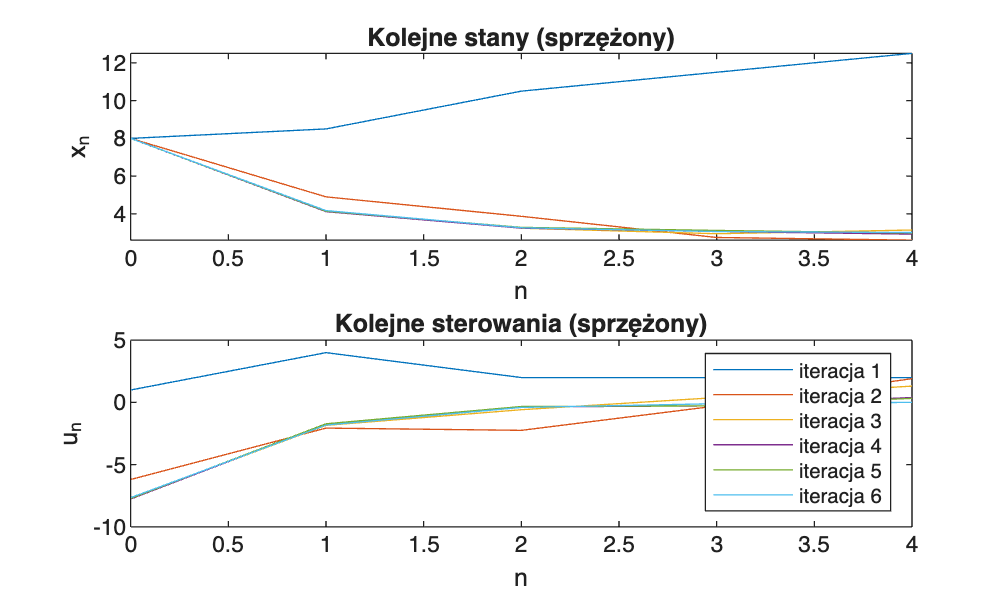

k = 0;
b_old = zeros(1,N);
d = zeros(1,N);

legenda = {};

while 1
    k = k + 1;

    for i = 2:N
        x(i) = r_stanu(x(i-1), u(i-1));
    end

    legenda{end+1} = ['iteracja ', num2str(k)];

    subplot(2,1,1);
    plot(0:N-1, x); hold on; title('Kolejne stany (sprzężony)'); xlabel('n'); ylabel('x_n');
    subplot(2,1,2);
    plot(0:N-1, u); hold on; title('Kolejne sterowania (sprzężony)'); xlabel('n'); ylabel('u_n');
    legend(legenda);

    J_plot_sprz(k) = J_fun(x, u);

    for i = N:-1:1
        p(i) = pn_fun(x(i), u(i), p(i+1));
        b(i) = bn_fun(x(i), u(i), p(i+1));
    end

    if k == 1
        d = -b;
    else
        c_FR = (norm(b)^2) / (norm(b_old)^2);
        d = -b + c_FR * d;
    end

    b_old = b;

    t = fminsearch(@(t) wyznacz_t_sprz(r_stanu, J_fun, x, u, N, d, t), t);

    u = u + t * d;

    if norm(b) < e || k >= K
        break
    end
end


J_plot_sprz

J_plot_sprz = 1.0e+03 *

    2.7690    0.3473    0.3288    0.3269    0.3268    0.3266


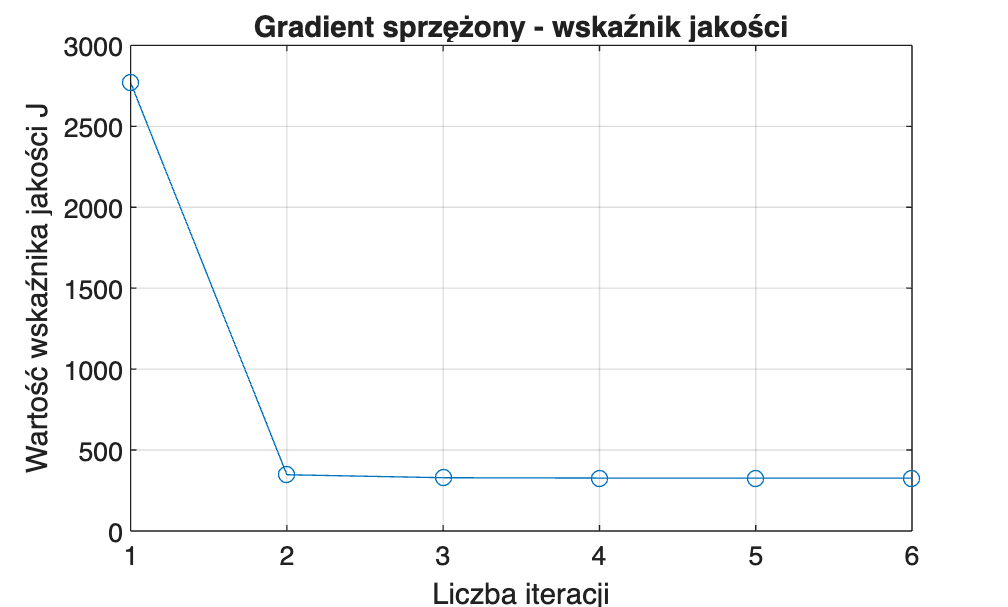


figure;
plot(1:k, J_plot_sprz, '-o');
title('Gradient sprzężony - wskaźnik jakości');
xlabel('Liczba iteracji');
ylabel('Wartość wskaźnika jakości J');
grid on;

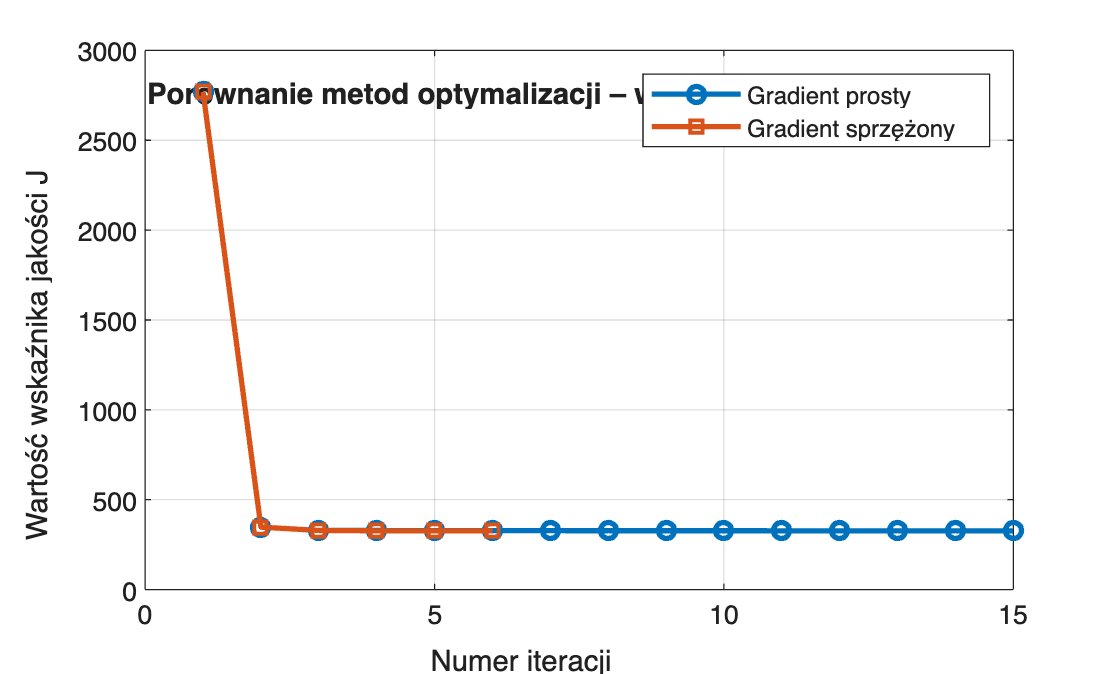


figure;
plot(1:length(J_plot_p), J_plot_p, '-o', 'LineWidth', 2, 'DisplayName', 'Gradient prosty'); hold on;
plot(1:length(J_plot_sprz), J_plot_sprz, '-s', 'LineWidth', 2, 'DisplayName', 'Gradient sprzężony');
title('Porównanie metod optymalizacji – wskaźnik jakości J');
xlabel('Numer iteracji');
ylabel('Wartość wskaźnika jakości J');
legend('Location','northeast');
grid on;


% Funkcja do minimalizacji po t (gradient sprzężony)
function J_val = wyznacz_t_sprz(r_stanu, J_fun, x, u, N, d, t)
x_new = x;
for i = 2:N
    x_new(i) = r_stanu(x_new(i-1), u(i-1) + t*d(i-1));
end
u_new = u + t*d;
J_val = J_fun(x_new, u_new);
end